# P2

clc
clear
close all

% 基本参数
Gqn0 = [16,64,256,1024,4096,16384,65536,262144]*1e-6;
vv   = [10,20,40,60];   % 车速m/s
n0   = 0.1;             % 参考空间频率

% 工况选择
Gqn0 = Gqn0(1);   % 选择路面等级
v    = vv(4);     % 选择车速

% 多项式参数
Q  = 0.218;
w  = 0.01571;
a0 = -22.38;
a  = [19.8 9.057 -6.142 0.5141];
b  = [32.41 -17.72 0.4945 0.6959];
Kv=a0+a(1)*cos(w*v)+b(1)*sin(w*v)+a(2)*cos(2*w*v)+b(2)*sin(2*w*v)+a(3)*cos(3*w*v)+b(3)*sin(3*w*v)+a(4)*cos(4*w*v)+b(4)*sin(4*w*v);

% simulink增益参数设定
k = 1/(Q*Kv*v);

% white noise参数设置
noise_power = 6*pi^2*n0^2*Gqn0*v;   % 噪声功率
sample_time = 0.0001;               % 采样时间
seed = 23341;                       % 随机种子

% 运行simulink模型
options=simset('Srcworkspace','current');
out=sim('P2_son.slx',[0,10]);

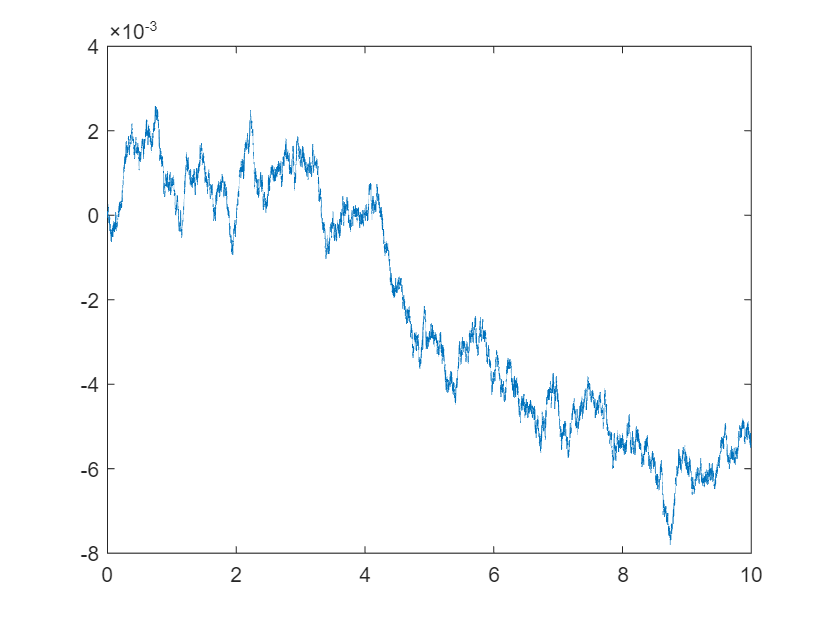

% 绘制路面不平度随时间变化
figure(1)
time           = out.simout.Time;
roud_roughness = out.simout.Data;
plot(time,roud_roughness);